Section Two

init();
N=1024; %number of samples in time and freq domain
n=0:N-1; %index for freq domain.
T=9; %signal period
Ts=T/N; %sample period
t=0:Ts:T-Ts;
Ts

Ts = 0.0088

ws = ((2*pi)/Ts)

ws = 714.8869

Tp = 1

Tp = 1


y=zeros(size(t));
t_in_ranges = find(( t >= 1 & t <= 2 ) | ( t >= 7 & t <= 8));
y(t_in_ranges) = sin((2 * pi * t(t_in_ranges)) / Tp);
make_plot(t, y, 'reconstructed waveforms', 'seconds', 'reconstructed y')

init();
N=16;
M=3;
m = -N/2:N/2-1;  % Frequency indices
cm = 2 * abs(m)  % Spectrum function

cm =     16    14    12    10     8     6     4     2     0     2     4     6     8    10    12    14


win = zeros(size(cm))

win =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m_between_negM_and_posM = find(m >= -M & m <= M)

m_between_negM_and_posM =      6     7     8     9    10    11    12


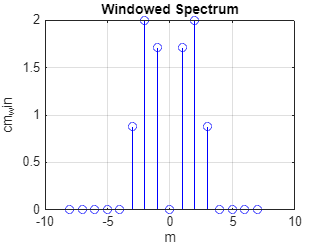

win(m_between_negM_and_posM) = hanning(length(m_between_negM_and_posM));
cm_win = cm .* win;  % Apply window
make_stem(m, cm_win, 'Windowed Spectrum', 'm', 'cm_win');

cm_win = cm .* win

cm_win =          0         0         0         0         0    0.8787    2.0000    1.7071         0    1.7071    2.0000    0.8787         0         0         0         0
